# Using functions provided by a Python package in electrophysiology analysis

*Elephant* (Electrophysiology Analysis Toolkit) is an emerging open-source, community centered library for the analysis of electrophysiological data in the Python programming language.

The focus of Elephant is on generic analysis functions for spike train data and time series recordings from electrodes, such as the local field potentials (LFP) or intracellular voltages. In addition to providing a common platform for analysis codes from different laboratories, the Elephant project aims to provide a consistent and homogeneous analysis framework that is built on a modular foundation.

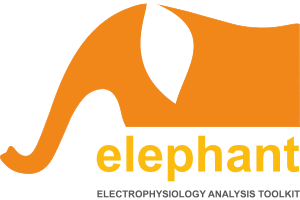

Elephant ([doi:10.5281/zenodo.1186602](https://doi.org/10.5281/zenodo.1186602); [RRID:SCR_003833](https://scicrunch.org/resolver/RRID:SCR_003833))

In this example we will explore how to import python code in MATLAB and perform additional analysis. 

## Check your environment    

First let's confirm that MATLAB recognizes the Python interpreter on your machine:

pyenv

Depending on our configuration, you can use arguments to this function to point to a specific interpreter in case you have access to more than one:

%% pyenv(Version="C:\\path\to\specific\python.exe") 

Or to set the run mode to "OutOfProcess" which allows Python to be run in a separate process (for example, to prevent MATLAB from crashing if the Python code fails):

%% pyenv(ExecutionMode = "OutOfProcess")

Now that you know that MATLAB can identify your specific Python interpreter, make sure all the Python packages needed for your project are properly installed in your system. In this case, we need the package elephant and other dependencies, so let's get them installed running the setup script: 

setup

## Basic syntax when using Python code in MATLAB

All Python functions in MATLAB have the same basic syntax:

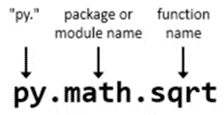

Now let's use the py syntax to call functions (py . package . function(args)); no need to use "import":

py.math.sqrt(42)

## **Use Python code in MATLAB**

In this MATLAB notebook, you can add tasks, which are simple point-and-click interfaces that can be added to a live script to perform a specific set of operations. Tasks represent a series of MATLAB® commands. You can display their output either inline or on the right. To see the MATLAB commands that the task runs, show the generated code.  Using the Live Task to include Python code we can make the process of using this file easier.  You can find the "**Run Python Code**" Live Task in the LIVE EDITOR tab, in the "Task" menu:

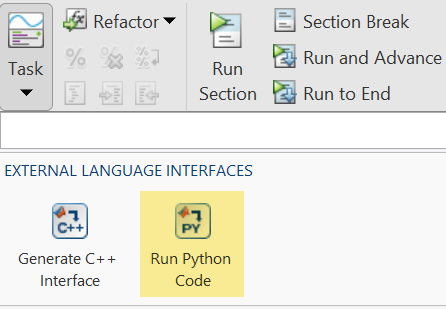

The Run Python Code task lets you interactively run Python code or files. The task automatically generates MATLAB code for your live script. Using this task you can: 

- Execute code in Python files.

- Return Python variables to the MATLAB workspace.

- Pass MATLAB data to the Python code.

Once you have the task in your notebook, you have the option to use a File or add your Python code directly. 

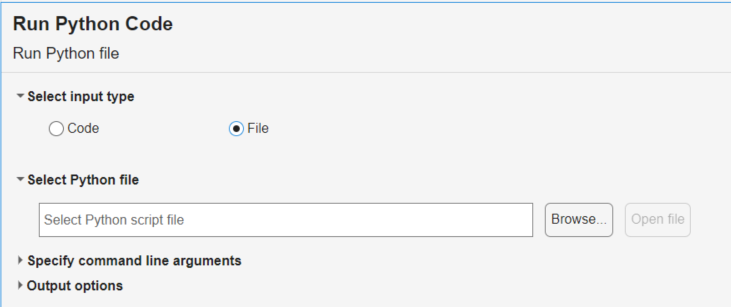

### Example 1: Adding python code

% Python code input
pycode = [...
"import numpy as np",...
"from quantities import ms, s, Hz",...
"from elephant.spike_train_generation import homogeneous_poisson_process, homogeneous_gamma_process",...
"",...
"",...
"t_start = 275.5 * ms",...
"print(t_start)",...
"",...
"t_start2 = 3. * s",...
"t_start_sum = t_start + t_start2",...
"print(t_start_sum)",...
"",...
"np.random.seed(28)  # to make the results reproducible",...
"spiketrain1 = homogeneous_poisson_process(rate=10*Hz, t_start=0.*ms, t_stop=10000.*ms)",...
"spiketrain2 = homogeneous_gamma_process(a=3, b=10*Hz, t_start=0.*ms, t_stop=10000.*ms)"...
];

try
    [spiketrain1, spiketrain2] = pyrun(pycode, ...
         [ "spiketrain1" "spiketrain2" ])
catch ME
    % Clear temporary variables from workspace and from Python
    clear pycode;
    rethrow(ME)
end

% Clear temporary variables from workspace and from Python
clear pycode;

The code above does basic statistics operations. We start by importing physical quantities (seconds, milliseconds and Hertz) and two generators of spiketrains - `homogeneous_poisson_process()` and `homogeneous_gamma_process()` functions from `elephant.spike_train_generation` module.

The function requires four parameters: the firing rate of the Poisson process, the start time and the stop time, and the refractory period (default `refractory_period=None` means no refractoriness). The first three parameters are specified as Quantity objects: these are essentially arrays or numbers with a unit of measurement attached. We specify `t_start` to be equal to 275.5 milliseconds

For spiketrains generation, in the python code provided we used one Poisson and one Gamma processes:

`spiketrain1 = homogeneous_poisson_process(rate=10*Hz, t_start=0.*ms, t_stop=10000.*ms)`

`spiketrain2 = homogeneous_gamma_process(a=3, b=10*Hz, t_start=0.*ms, t_stop=10000.*ms)`

The important properties of a `SpikeTrain` are:

- `times` stores the spike times in a numpy array with the specified units;

- `t_start` - the beginning of the recording/generation;

- `t_stop` - the end of the recording/generation.

- `magnitude`

We can then use the output to extract information and convert it into something that MATLAB can use:

value1 = spiketrain1.magnitude
V1 = double(value1)

value2 = spiketrain2.magnitude
V2 = double(value2)

Let's now use the output to create a basic raster plot:

num_spikes = length(V1)
plot([V1; V1], [ones(1, num_spikes); ones(1, num_spikes)+1],'k')

num_spikes2 = length(V2)
plot([V2; V2], [ones(1, num_spikes2); ones(1, num_spikes2)+1],'k')


Can you suggest a better way to create this raster plot? 

%% ADD YOUR CODE HERE TO CREATE OTHER RASTER PLOT




### Example 2: Using an existing python file to perform SPADE analysis

SPADE is a method to detect repeated spatio-temporal activity patterns in parallel spike train data that occur in excess to chance expectation. In this tutorial, we will use SPADE to detect the simplest type of such patterns, synchronous events that are found across a subset of the neurons considered (i.e., patterns that do not exhibit a *temporal extent*). We will demonstrate the method on stochastic data in which we control the patterns statistics. 

A python code has been provided to us in support of the analysis.  Let's review the Python code first! Open the file `spade.py` and explore its content. 

open 'spade.py'

Now, add the Live Task and import the file

**Pause - Add your task "Run Python Code" here and click the Run button in the Live Task once you're ready**

Can you now create a raster plot with the new set of spiketrains?

% ADD HERE YOUR CODE FOR ADDITIONAL ANALYSIS


